# Expand Example 3.4:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

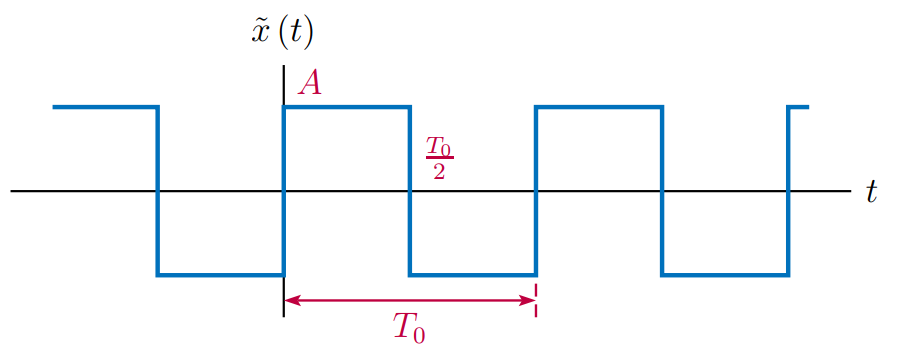

For the square wave shown, the TFS coefficients are

$a_{k}=0$  for  $k=0,1,\ldots,\infty$,    and    $b_{k}=\left\{\begin{array}{c l}
\frac{4A}{\pi k},& k\;\textrm{odd}\\
0, & k\;\textrm{even}
\end{array}\right.$

Compute and graph a $M$-harmonic approximation to the signal.

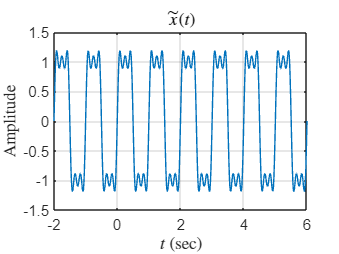

M = 5; % Number of harmonics to include
%
A = 1;   % Pulse amplitude
T0 = 1;  % Pulse period
% Set TFS coefficients
k = [1:30];
bk = zeros(size(k));
k2 = [1:2:29];   % Odd indices
bk(k2) = 4*A./(pi*k2);
t=[-2:0.01:6];   % Vector of time instants
omg0 = 2*pi/T0;  % Fundamental frequency
% Compute the approximation
xtilde = 0;
for kk=1:M
  xtilde = xtilde+bk(kk)*sin(kk*omg0*t);  
end;
% Graph the finite-harmonic approximation
plot(t,xtilde); grid;
set(0,'defaultTextInterpreter','latex');
axis([-2,6,-1.5,1.5]);
title('$\tilde{x}(t)$');
xlabel('$t$ (sec)');
ylabel('Amplitude');

set(0,'defaultTextInterpreter','tex');